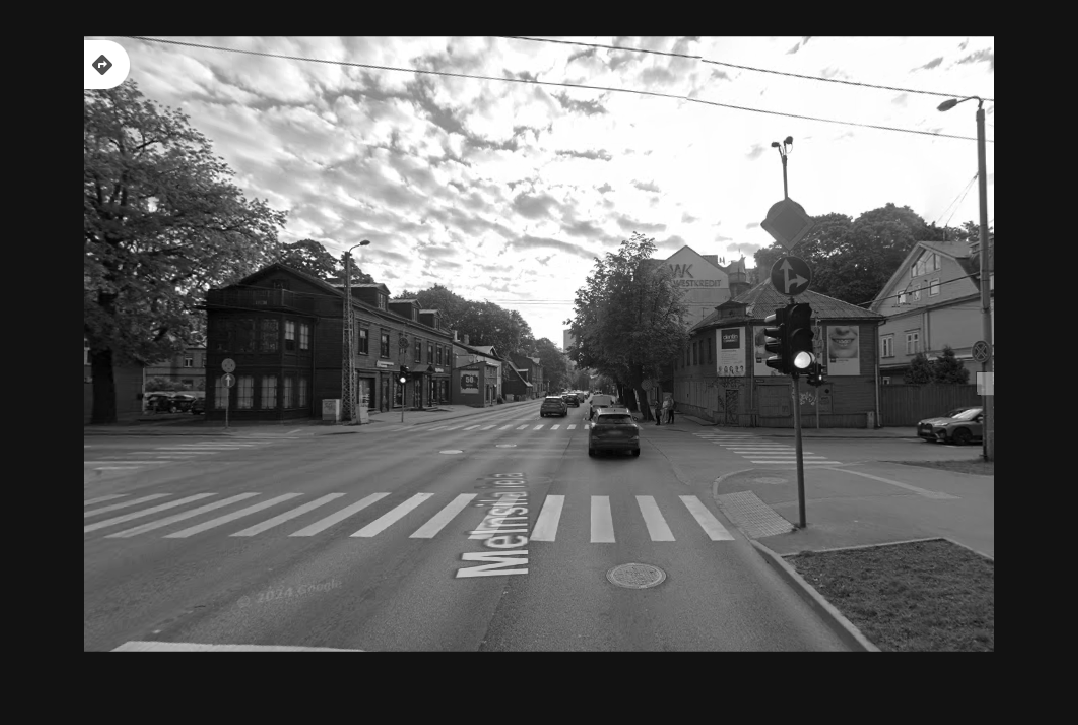

clear all;
close all;

img = imread('bilde3.png');
gray = im2gray(img);
imshow(gray);

Find centers and radius of circles

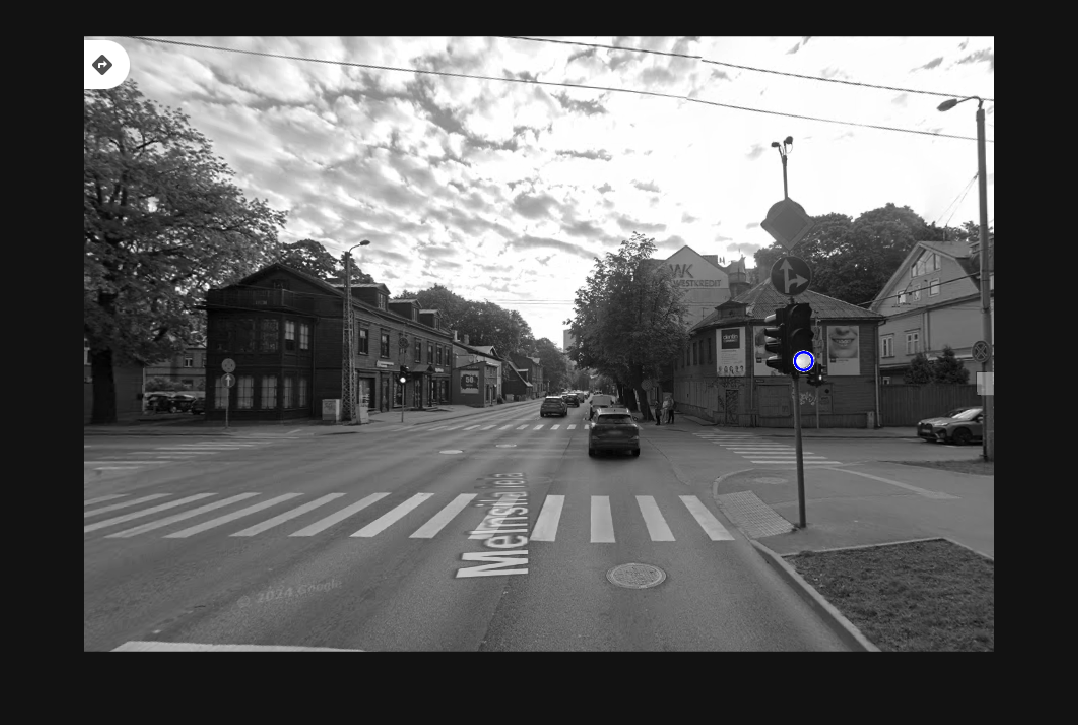

Rmin = 8;
Rmax = 20;
% Find bright objects
[centersBright, radiiBright] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'bright', 'Sensitivity', 0.85);
% Find dark objects
[centersDark, radiiDark] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'dark', 'Sensitivity', 0.85);
viscircles(centersBright, radiiBright, 'EdgeColor', 'b');

viscircles(centersDark, radiiDark, 'EdgeColor', 'r', 'LineStyle', '--');
%h = imdistline;
%fcn = makeConstrainToRectFcn('imline', get(gca, 'XLim'), get(gca, 'YLim'));
%setDragConstraintFcn(h, fcn);